Read test images.

img_lenna=imread("Lenna.jpg");
img_emu=imread("emu.jpg");
img_nene=imread("nene.jpg");
img_miku=imread("miku.jpg");

Inner function implementation.

% I1 = impyramid(img_lenna, 'reduce');
% I2 = impyramid(I1, 'reduce');
% I3 = impyramid(I2, 'reduce');
% figure, imshow(img_lenna)
% figure, imshow(I1)
% figure, imshow(I2)
% figure, imshow(I3)

Generate the image pyramid.

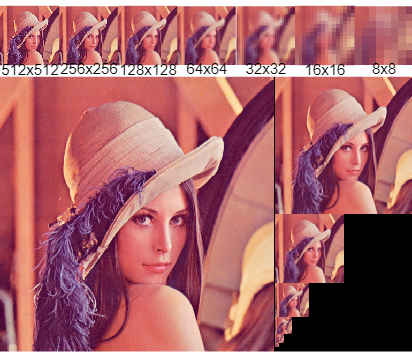

[g_pyramid,l_pyramid]=generate_pyramids(img_lenna,5,2);
% g_pyramid_concat=concatenate_image_pyramid(g_pyramid,2);
% l_pyramid_concat=concatenate_image_pyramid(l_pyramid,2);
% figure,imshow(g_pyramid_concat)
% figure,imshow(l_pyramid_concat)
display_image_pyramid(g_pyramid,2);

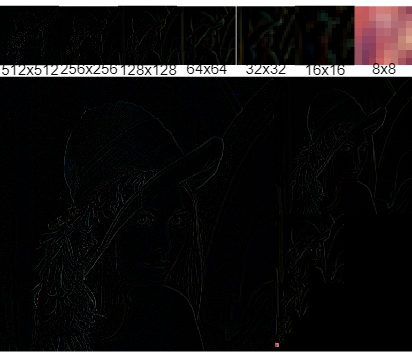

display_image_pyramid(l_pyramid,2);

Hybrid images.

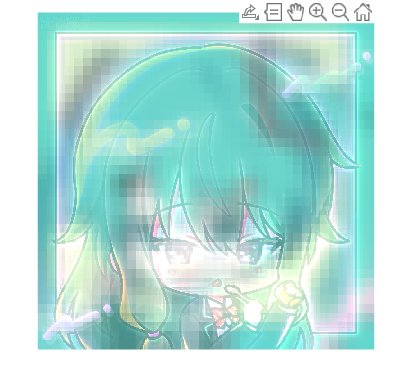

% [g_pyramid,l_pyramid]=generate_pyramids(img_nene);
% display_image_pyramid(g_pyramid,2);
% display_image_pyramid(l_pyramid,2);
hybrid_miku_nene=hybrid_image(img_miku,img_nene,5,'kernel_size',7,'sigma',2);
figure,imshow(hybrid_miku_nene);

Implement the functions manually.

function [g_pyramid,l_pyramid]=generate_pyramids(img,kernel_size,sigma)
    [m,n,c]=size(img);
    max_n=ceil(log2(m)-3);
    g_pyramid={img};
    l_pyramid={};
    for i=1:max_n
        gaussian_kernel = fspecial('gaussian', [kernel_size kernel_size], sigma);
        img_blur=imfilter(img,gaussian_kernel,"replicate","same","conv");
        l_pyramid(i,:)={img-img_blur};
        img=imresize(img_blur,0.5,"nearest");
        g_pyramid(i+1,:)={img};
    end
    % disp(max_n+1)
    l_pyramid(max_n+1,:)={img};
end



function display_image_pyramid(imgs, margin)

    N = size(imgs, 1);
    
    canvas = concatenate_image_pyramid(imgs, margin);
    [ch,cw,~] = size(canvas);
    margin = margin / N / cw;
    pm = margin;
    figure;
    for i = 1:N
        % disp([pm 0.6 1/N 0.45])
        subplot('Position', [pm 0.8 1/N 0.2]);
        imshow(imgs{i});
        text(0.5, -0.2, sprintf( '%dx%d', size(imgs{i},[1 2]) ), ...
             'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom', ...
             'FontSize', 10, 'Color', 'k', 'Units','normalized');

        pm = pm + 1/N + margin;
    end
    % disp(margin)
    subplot('Position', [margin margin 1-margin 0.8-margin]);
    imshow(canvas);
    set(gcf, 'Position', [100, 100, cw, ch*1.3]);

end



function canvas=concatenate_image_pyramid(imgs,margin)

    [m,n,c]=size(imgs{1});
    canvas=zeros([m ceil(n*1.5+margin) c],"uint8");
    canvas(1:m,1:n,1:c)=imgs{1};

    pm=1;
    pn=n+1+margin;
    for i=2:size(imgs,1)
        [m,n,c]=size(imgs{i});
        canvas(pm:pm+m-1,pn:pn+n-1,1:c)=imgs{i};
        pm=pm+m;
    end

end



function output = hybrid_image(img1, img2, N, varargin)
    
    ip=inputParser;
    addParameter(ip, 'kernel_size', 5);
    addParameter(ip, 'sigma', 2);
    parse(ip,varargin{:});
    kernel_size=ip.Results.kernel_size;
    sigma=ip.Results.sigma;

    % Step 1: 生成高斯和拉普拉斯金字塔
    [g_pyr1, l_pyr1] = generate_pyramids(img1, kernel_size, sigma);
    [g_pyr2, l_pyr2] = generate_pyramids(img2, kernel_size, sigma);
    
    % Step 2: 选择金字塔层次进行融合
    hybrid_pyr = cell(size(g_pyr1));
    
    % Step 3: 构建混合金字塔
    for i = 1:N
        if i <= length(l_pyr2)
            hybrid_pyr{i} = l_pyr2{i}; % 使用第二幅图像的高频部分
        end
    end
    for i = N+1:length(g_pyr1)
        hybrid_pyr{i} = g_pyr1{i}; % 使用第一幅图像的低频部分
    end
    % figure, imshow(concatenate_image_pyramid(hybrid_pyr,2));

    % Step 4: 重建混合图像
    output = hybrid_pyr{N+1};
    % figure, imshow(output,"InitialMagnification","fit")
    for i = N:-1:1
        upscale_size=size(hybrid_pyr{i});
        upscale_size=upscale_size(1:2);
        output = imresize(output, upscale_size, 'nearest') + hybrid_pyr{i};
    end

end


